# Pico2 Controlled Current Mirror

18 Jan 25 B.R.

## Objective

Control our prior PWM current mirror circuit (and oscope) with a Raspberry pi Pico2. Why a Pico2, and not the older Pico? Tried that in a previous class and the Pico has an ugly hardware bug in its data acquisition system that wrecks its ability to do accurate fft's ... see [strangeDiode.mlx].

## Methods

Reductionism is a key meta-method. Here's a first (top-down) proposal:

- establish communication with the Pico2

- modify oscope1.ino --> pscope.ino and co-modify oscope4.m --> pscope.m

- modify volts2pwm --> pvolts2pwm and freq2pwm --> pfreq2pwm (which will require repeating calibration and `polyfit` processes).

- modify the function generator parallel capacitance to match a useful range of frequencies we can measure with the Pico2

- automate a Bode plot measurement of an RC circuit (chosen to have a corner around the mid-frequency).

Here's where I deviate from a "lab report" because this is a lab notebook -- a work in progress. 

### Communication with the Pico2

Duck-duck-go-ing "pico2 programming in arduino ide" led to [https://coolplaydev.com/pico-with-arduino-ide](https://coolplaydev.com/pico-with-arduino-ide) -- the top hit that explicitly contained "pico2". It appears to require the new IDE (2.2.1 or later, not the 1.18... version that I've been hanging onto). So first step is getting the latest version 2.2x IDE, and then Ardino IDE -> Settings... -> Additonal board manager URLs: -> paste: [https://github.com/earlephilhower/arduino-pico/releases/download/global/package_rp2040_index.json](https://github.com/earlephilhower/arduino-pico/releases/download/global/package_rp2040_index.json) and click OK. 

Now Select Board -> Raspberry Pi Pico 2 is available. I already did this and my Pico is plugged into a (long) solderless breadboard upside down (so I can read the pin labels on the bottom) -- so running Examples --> blink isn't an easy option -- although I can tweak it. GPIO16 is easiest to access so connect it to a 1k resistor in series with an external LED.

Before running, the IDE asked me if I wanted to install ... I forgot the message but said yes, and a bunch of rp2040 and rp2350 (pico2) packages were installed. And it didn't work -- "Compilation error: fork/exec ... bad CPU type in executable" Gotta love C error messages -- makes you appreciate Matlab more? Quit the IDE, tried again ... did another search on the error --> [https://forum.arduino.cc/t/bad-cpu-type-in-executable-compile-error/1064440/9](https://forum.arduino.cc/t/bad-cpu-type-in-executable-compile-error/1064440/9) I need to install Rosetta 2, an Intel emulator for my Apple Silicon. Searching how to do that --> terminal -> `softwareupdate --install-rosetta`

Curious that it didn't require sudo or password, just agree to Apple's terms. Restarted the IDE ... upload worked, and I have a blinking LED

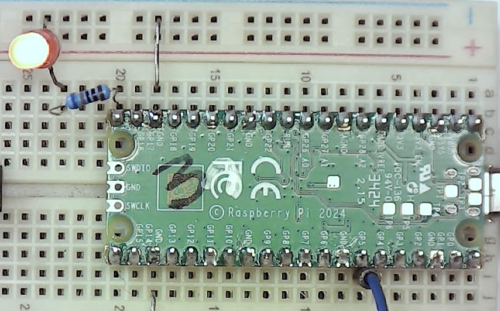

Nothing easy about that ... on a PC or Intel Mac you might skip some steps, but "gotta do what ya gotta do..." Imagine if we had been more aggressive, less reductionist, and combined several of the Methods 1-5, how much time might have been wasted to find the nature and fixes of the problems. 

### oscope1.ino --> pscope.ino 

There are many new things we might want to do with the pico2, but "baby steps" would be wise. On the other hand, I have some experience with the first Pico, so we can borrow from that (see p1_SwitchingNanoToPico.mlx). Here's the first code, with one new command (and lots of more minor tweaks). Note, I had to reboot my computer to get this to upload. After blink uploaded fine and was blinking, I kept getting an error that the pico wasn't found. Quitting IDE had no effect, the problem was the OS holding onto or blocking the serial port. I hate rebooting -- it's really disruptive and inefficient!

- new `d <microseconds> `command adds a delay between successive measurements. This is needed to see "slower" waveforms -- because the Pico is so much faster than the Nano.

- increased `numsamp` from 400 to 5000 -- we could increase it much more, since we have many MB of memory vs. 2kB on the Nano. Note I first changed it to 1000, but then increased to 5000 for better statistics. I tried to reprogram the Pico to 1000, but the IDE won't find it -- rather than reboot, I'm leaving the Pico at 5000 samples and adjusting pscope.m to match. 

- We're very explicit about the sizes of variables: uint8_t, uint16_t, uint32_t instead of int and long, which aren't consistently defined in C (C requires only that sizeof(short) <= sizeof(int) <= sizeof(long), but doesn't specify what those sizes are).

- I moved the analogOutputPin to a more convenient place on the breadboard -- GPIO15. Make sure your hardware reflects this definition!

- The first line of setup(), `Serial.ignoreFlowControl(true)`, *should* fix the previous need to reboot. Found this tip snooping around the Internet. 

- `analogReadResolution` and `analogWriteResolution` are now settable, up to 10, 12, or 14 bits. I'm not convinced that more than 10 bits improves accuracy. Make sure you use the right factor to convert `adu2Volts`.  

- Note how simple the `d <delayMicroseconds>` command is implemented -- there is no error or bounds checking, so be careful not to set a value too large, or the Pico will take a long time to complete the next b command. `measureWaveformsBinary` calls two (symmetric) delays, everything else is the same as before. Without slowing down the Pico, we won't be able to measure low frequencies (even with 5000 data points) -- the sample rate 

Move your LED and series resistor to `analogOutPin` and verify in the IDE's Serial Monitor that p <value> has the expected (qualitative) behavior over the full range of values. If not, troubleshoot. If so, then we're ready to move to step 2b.

### oscope4.m -> pscope.m

First, is this a good idea? Should we start with oscope1.m and work our way up? Think about the pros and cons ... 

Building complex systems requires many reductionist decisions of this nature. Recall the history of oscope1-4: 1 was bare bones; 2 calibrated the time axis; 3 added triggering with `trim`, `arddeskew`, and numerical data in the title, and 4 refactored 3 to clean up the workspace using the `dat` data structure. We want `dat`! Debugging can be harder in the data structure, but the bugs I anticipate (hope) aren't at that level. So my gut says to go for 4. Here's what I came up with (starting from oscope4.m) -- not much of substance changed:

- `ard` was renamed `pico. `

- `dat.numBytes` was added to match `NUMSAMPLES` in the .ino file, and putting it in the loop anticipates it could become dynamic (variable). 

- near the end, `pause(.1)` was added to slow the frame rate (FPS) down. With the pause commented out, I measure ~43 FPS that was annoying to look at -- "your mileage may vary".

### Voltage divider

We'll have to adjust `dat.trimThresh` to around `mean(dat.data)` after we've hooked up the function generator through an appropriate voltage divider. Pico's maximum voltage = 3.3V, vs. the Nano's vref ~ 5V. We seek a pair of resistors such that 12V * R1 / (R1+R2) < 3.3V ... see if you can come up with a suitable pair that's in your kit. Note that the voltage divider will have a Thevenin resistance = R1 || R2, so we don't want them too large, nor too small that they waste power and load the function generator. 

I measured:

R1 = 1997; % 2k
R2 = 5103; % 5.1k
fprintf('divided voltage < %.1fV\n', 12 * R1/(R1+R2))

divided voltage < 3.4V


A little higher than 3.3V, but there's a ~1.5V dropout voltage with the LM317, giving it a maximum output ~10.3V, and likewise the function generator never reaches its 12V power supply "rail", and finally, I always have a 10k resistor in series with A0 and A1 just in case ... 

Connect the LM317 output to the voltage divider, and the divider output to A0 and A1 through a 10k series resistor (for extra protection): 

pscope;

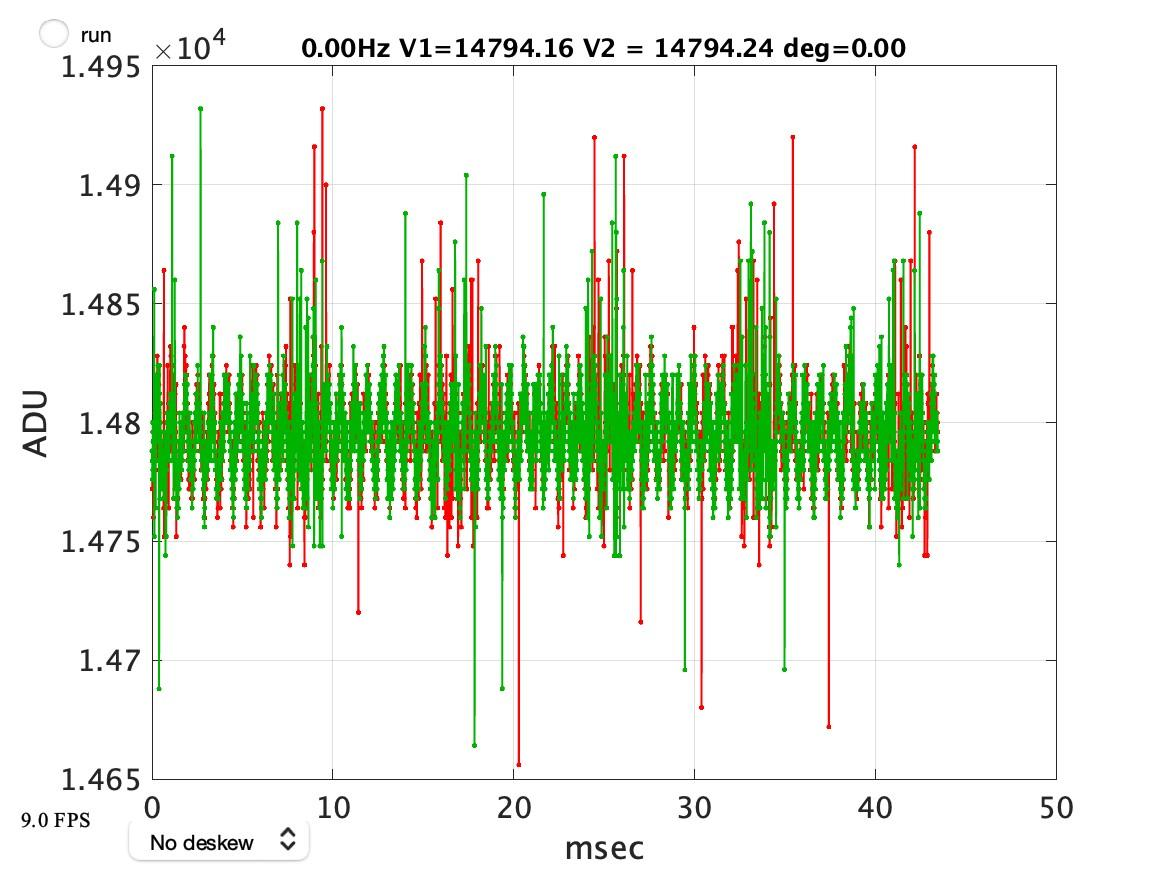

That's a lot of noise, but also a lot of signal. The frequency domain tells more:

`aspectrum(dat.data, dat.sr);`

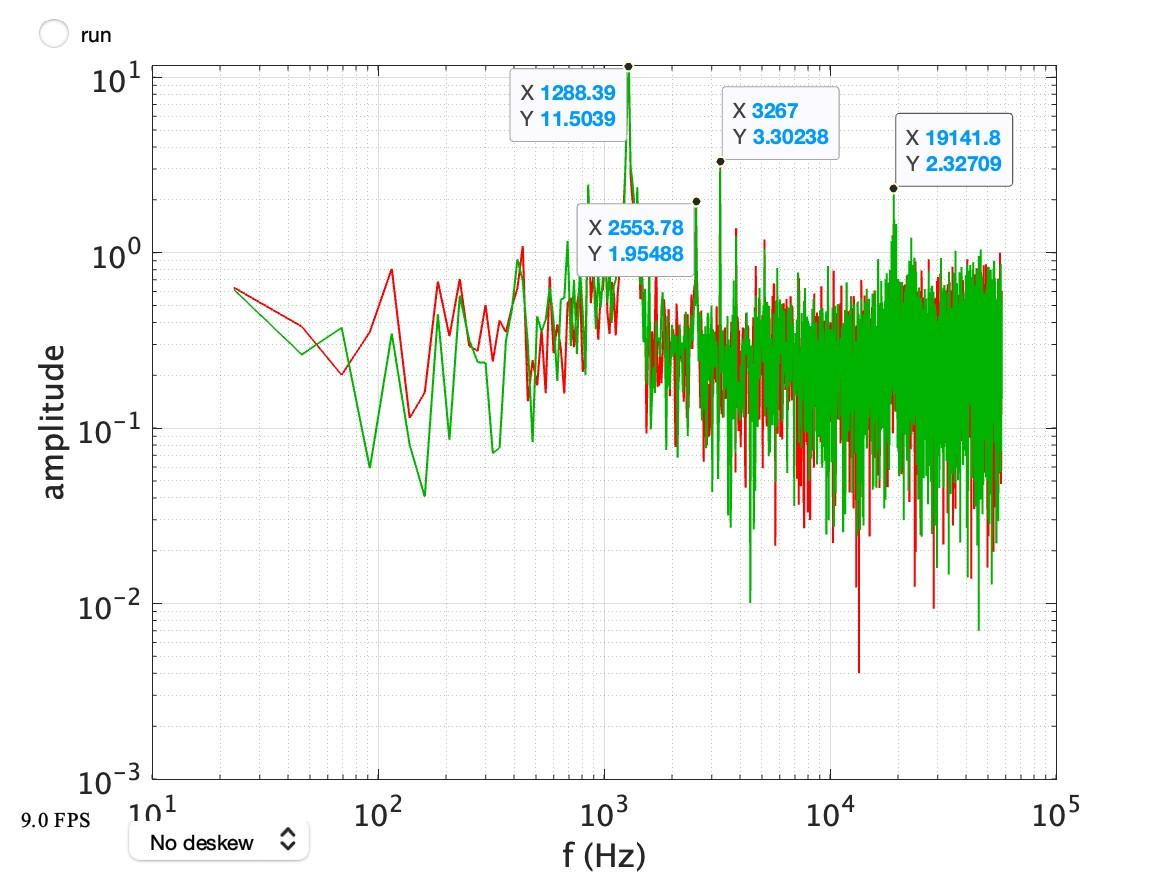 

The noise is high frequency, 1288Hz at 11.5ADU = 

vref = 3.252; % volts measured on ADC_VREF pin
adu2v = vref / (2^14 - 1);
fprintf('peak noise signal = %.1fmV\n', 11.5*adu2v*1000)

peak noise signal = 2.3mV


fprintf('rms noise = %.1fmV\n', mrms(dat.data)*adu2v*1e3)

rms noise = 3.0mV
rms noise = 3.1mV


So 2/3 of the noise is in the 1.29kHz peak, but it *looks* much more than it is. 

Adding a 100nf shunt between A1 and ground gets rid of most of it but reveals another issue: 

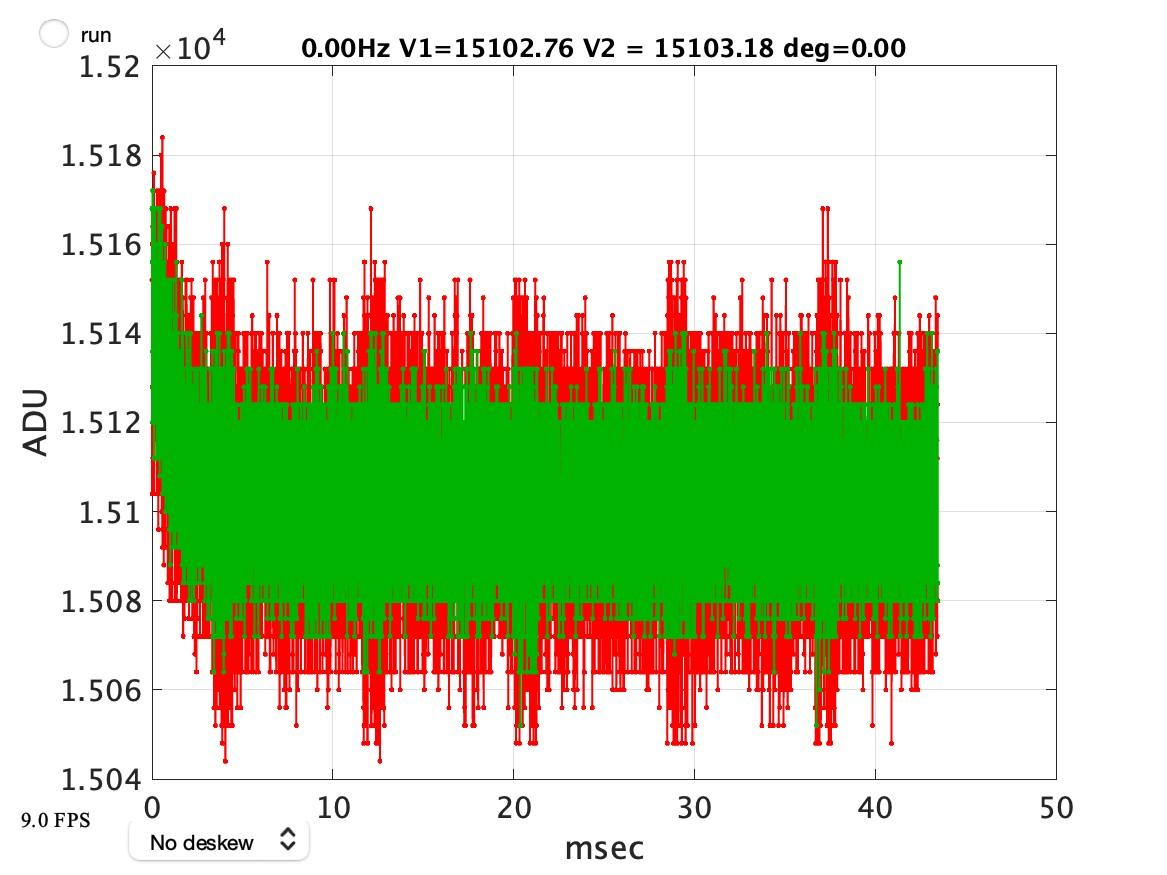

The data is again tight, within a few ADU, but why did adding a C change the mean value?! That, along with the fast exponential drop upon data acquisition beginning suggests there isn't enough current to hold the voltage on A0 and A1. Reducing the 10k series resistor to 1k almost eliminates the initial transient, and removing it altogether and moving the shunt capacitor between A1 and adjacent AGND pins has the largest reduction

fprintf('rms noise = %.1fmV\n', mrms(dat.data)*adu2v*1e3)

rms noise = 5.5mV
rms noise = 3.8mV


### Stability testing

Before attempting calibration of pvolts2pwm and pfreq2pwm, it could be a good idea to verify stability. We can't expect the system to work better than its inherent variability, so let's do a quick measure of that -- by taking 100 data sets and computing mean, standard deviation, and coefficient of variance of the amplitudes, phases, and frequencies. Note A0 and A1 are jumpered together, to the output of the voltage divided sine wave set at maximum frequency on the middle frequency jumper. Why do I run the loop backwards (starting at 100 and decrementing)?

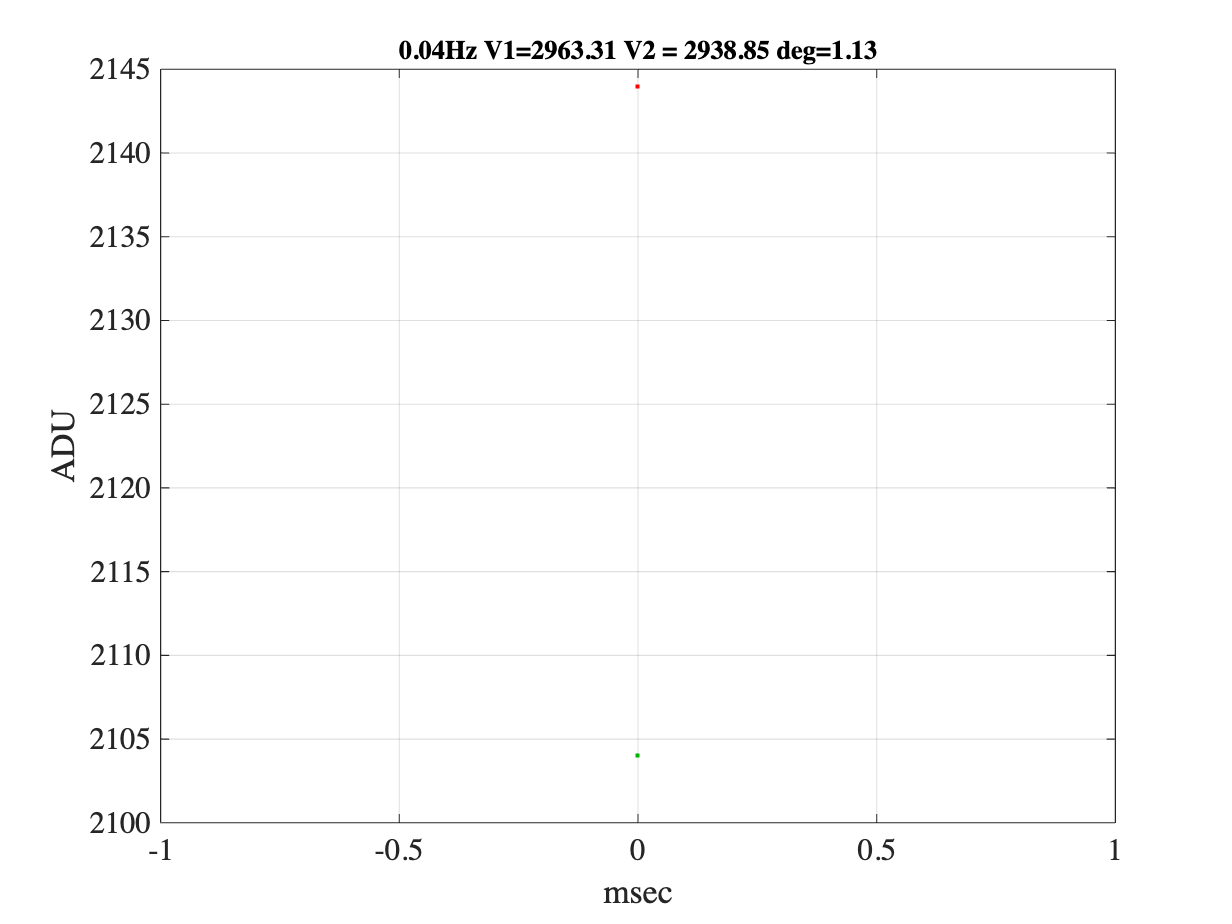

tic; for i=100:-1:1
    a(i,:) = abs(dat.ampl); 
    dphase(i) = diff(dat.theta); 
    freq(i) = dat.freq;
    dat.runOnce = true; 
    pscope; 
end

toc
fprintf('amplitude CV = %g\n', std(a)./mean(a));
fprintf('phase shift = %f +- %f degrees\n', mean(dphase), std(dphase))
fprintf('freq = %.1f+-%.1fHz, CV = %g\n', mean(freq), std(freq), std(freq)/mean(freq))

Efficient memory management -- the first iteration allocates the entire arrays. Those results are impressive numbers (to me)!! The variances and errors are so small in part because we they're averages of 200,000 voltages (measured in a mere 14 seconds). Your mileage may vary depending on your hardware ... 

## Automated DC voltage source: pvolts2pwm

Time to calibrate automated control. Should we do the function generator first or last? Do we have to change the current mirror hardware (i.e., the emitter follower potentiometer setting)? We should expect yes, because the Nano has vref ~ 5V, so a smaller $R_E$ will be needed to achieve the same mirror current ~1mA at 3.3V. Recall that changing $R_E$ changes the slope of volts vs. pwm curve, and we seek a slope that maximizes the (approximately) linear range of PWM values. My gut says to start with the LM317, so I set its 10k pot to maximum (and maximum output voltage), disconnected the function generator output from the voltage divider (and plugged it into an unused column of the breadboard so it doesn't short or cause mischief), and plugged the LM317 output into the voltage divider, which connects through a 10k resistor to A0 and A1. I soldered a wire underneath the board between the PWM filter input and a spot near GPIO15 so the PWM filter input wire doesn't inconveniently cross over the relocated function generator board. 

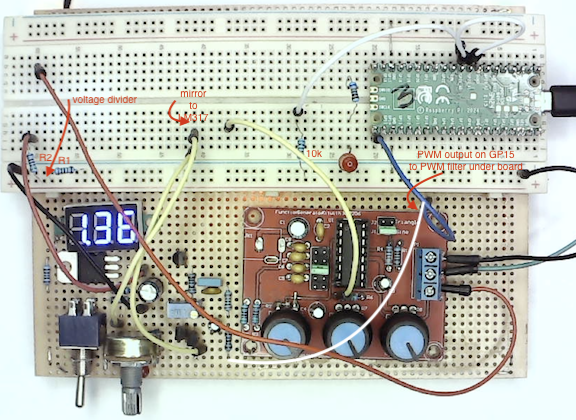

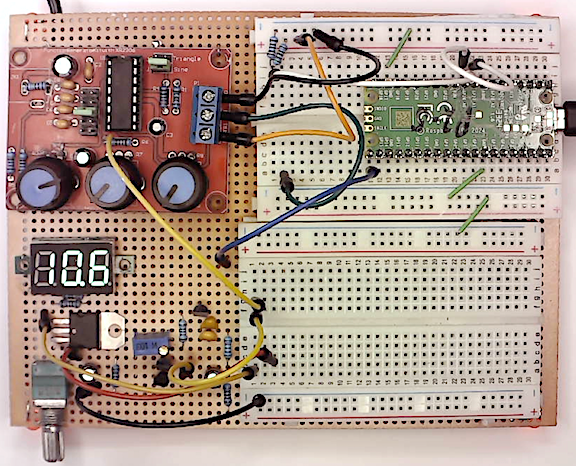

Figure 2. Reorganized boards to fit a Pico. 

Let's calibrate: 

adu2v = 3.22 / (2^14 - 1); % measured with DVM
mean(dat.data) * adu2v * (R1+R2)/R1

I measure 10.26V with the DVM. Where's the discrepancy? Replaced the 10k resistors in series with A0 and A1 with a 1k protection resistors --> 

That strongly suggests the input impedance of the Pico's A0 is lower than the Arduino. That's not surprising -- because a faster ADC has to charge its input capacitance faster. To avoid loading errors, we'll use less protection resistance, and have to be more careful not to overvoltage the 3.3V inputs. 

See how much we're learning and changing, and we haven't started the pwm-voltage sweep yet!

Another little time-waster: out of habit, I thought I'd set a high PWM value to verify the output voltage dropped: `writeline(pico,'p 180')` and there was no change -- why not? Troubleshooting with 1k resistor and LED in series with GPIO15 shows the pin is on ... ahhh it hit me ... have you figured it out? 

Pico is set up for 10 bit PWM, so 180PWM =  $180PWM * \frac{3.3V}{1023PWM}$ ~ 0.58V, not enough to turn on the two $V_{BE}$ voltages of the emitter follower and current mirror.

Stretching out the PWM range to 1023, ignoring the first ~1/3 of 3.3V below threshold. A0 and A1 shorted together, connected to the voltage divider with 1k in series. After observing some glitches, I added a 100nf "bypass capacitor" between A0 and ground, and the glitches disappeared. 

flush(pico); % just in case ... 
pwmVal = round(linspace(300,1023,50));
tic;
for i= 1:length(pwmVal)
    writeline(pico,sprintf('p %d', pwmVal(i)));
    dat.runOnce = true;
    pscope;
    vmeas(i) = mean(dat.data(:,1));
    nmeas(i) = std(dat.data(:,1));
end
toc
writeline(pico,'p 0'); % reset
adu2vd = adu2v*(R1+R2)/R1; % voltage divider compensated
v317 = vmeas * adu2vd;
errorbar(pwmVal, v317, nmeas*adu2vd)
grid; axis tight; xlabel('pwmVal'); ylabel('LM317 output/Volts')
indx = 1:length(pwmVal); % = v317 < .98 * max(v317) & v317 > 1.1 * min(v317); % boolean
plot(pwmVal, v317, '.-', pwmVal(indx), v317(indx),'d')
axis tight; grid; xlabel('PWM'); ylabel('volts')
% fit a polynomial
poly = polyfit(v317(indx), pwmVal(indx), 5); % flipped x and y 
err = pwmVal - polyval(poly,v317);
plot(v317, err, '.-'); grid;
xlabel('volts'); ylabel('PWM error');
save pwmCalData20jan24 pwmVal v317 
fprintf('%g ', poly)

A few random tests show it works like a champ. Let's quantify: 

vset = linspace(1.5,10.2,50)'; % try to set these 50 voltages
meanV = zeros(size(vset)); stdV = meanV; % allocate result vectors
pvolts2pwm(vset(1), pico); pause(1); % extra settling time
tic; 
for i = 1:length(vset)
    pvolts2pwm(vset(i), pico); 
    dat.runOnce = true; pscope; 
    meanV(i) = mean(dat.data(:,1))*adu2vd;
    stdV(i) = std(dat.data(:,1))*adu2vd;
end
toc
err = meanV - vset;
errorbar(vset, err, stdV); 
xlabel('target voltage / V'); ylabel('measured - target / V');
grid;

Not bad ... we used a 5th order polynomial, and the residual (error) looks 6th order (parabolic with 3 humps). The 5th order polynomial (and our restriction of test data to pwmVal > 300) gave us better fit without using indx to exclude the tails. Reflect on what else surprised you ... Ready to move on to `pfreq2pwm`? 

## Automated function generator: pfreq2pwm

We won't mess with the emitter follower pot anymore. Just unplug the LM317 output from the voltage divider (and plug into a safe, unused column), and replace with the function generator output. Likewise, move the LM317 mirror jumper to a safe unused column and connect the function generator's R6 jumper to the mirror. Click on the pscope run button, and the waveform looks a little distorted -- it pops back to steady upon removal of the 0.1uf "bypass" capacitor. 

I reduced the amplitude to below the obvious clipping level. With the frequency jumper in the middle position, the lowest frequency I can stably trigger is ~290Hz, well above the function generator's lowest frequency on this range. The highest with the frequency jumper in the middle position is ~4638Hz, well below the Nyquist frequency = dat.sr/2 ~57.5kHz. Moving the frequency jumper up results in aliasing of the highest frequencies, so let's go back to the middle jumper position, and use the delay feature to sample lower frequencies. Setting the frequency pots to minimum (make sure the mirror is off,  writeline(pico,'p 0'), a little trial and error, and writeline(pico,'d 5') reliably triggers one stable period of ~167Hz. Turning the two frequency pots to their maximum results in ~4577Hz, 

fprintf('fmax/fmin = %.1f\n', 4577/167)

The mirror may let us expand that range -- maybe it can sink more current since the pots are in series with 5.1k$\Omega$. Indeed, `writeline(pico,'p 1023')` sets the frequency to ~12420kHz (with an excruciatingly long time constant). Ah, but now `fmin` is about 4577 because the two frequency pots are at maximum. Turning the pots to minimum, the maximum `'p 1023'` frequency is ~8089Hz.

fprintf('fmax/fmin = %.1f\n', 8089/167)

`fmax` is still well below the Nyquist frequency, above (about 1/2 of what it used to be because of the 'd 5' delay).  

### Time constants

I'm curious about the slow frequency settling time, so let's explore it empirically, hoping that characterizing it might yield insights into its cause and remedy. The frequency has been stable at 8088Hz for many minutes after a `'p 1023'` command. So let's start a timer, writeline(pico, 'p 0') and measure the resulting frequency evolve over the next few minutes. Its tempting to use the loop index as time, but its more accurate to read a clock instead. In code:

n = 100; % numsamples
secs = zeros(n,1);
freqs = secs;
writeline(pico,'p 0');
tic; % start the stopwatch
for i=1:n
    dat.runOnce = true; 
    pscope;
    secs(i) = toc;
    freqs(i) = dat.freq;
    pause(.25);
end
plot(secs, freqs); grid; axis tight;
xlabel('time / seconds'); ylabel('frequency / Hz')

That took seemingly forever and showed pretty much immediate convergence, for a decreasing frequency. 

Let's jump the other way.

secs = zeros(n,1);
freqs = secs;
writeline(pico,'p 1023');
tic; % start the stopwatch
for i=1:n
    dat.runOnce = true; 
    pscope;
    secs(i) = toc;
    freqs(i) = dat.freq;
    pause(.25);
end
plot(secs, freqs); grid; axis tight;
xlabel('time / seconds'); ylabel('frequency / Hz')

Note that here it wouldn't make sense to measure a coefficient of variance -- of an exponential. And the time constant may not be *horrendous* considering we started at 168Hz around 0 seconds. But even after 75 seconds (i.e., "forever"), the frequency still is increasing, still hasn't stabilized!! 

We could continue analyzing and modeling and ... but a practical solution is to always leave the pico in 'p 1023' state for a looooong time, and sweep the frequency downward. 

### Calibrating pfreq2pwm

Copying and tweaking code from pvolts2pwm: 

writeline(pico,'d 5'); % just to make sure
pwmVal = round(linspace(1023,300,50)');
fmeas = zeros(size(pwmVal));
tic;
for i= 1:length(pwmVal)
    writeline(pico,sprintf('p %d', pwmVal(i)));
    dat.runOnce = true; pscope;
    fmeas(i) = dat.freq;
end
writeline(pico,'p 1023'); % reset

plot(pwmVal, fmeas)
grid; axis tight; xlabel('pwmVal'); ylabel('freq / Hz')
pv5 = polyfit(fmeas/1000, (pwmVal/512)-1, 5); % flipped x and y 
err5 = pwmVal - (polyval(pv5,fmeas/1000)+1)*512;
plot(fmeas, err5, '.-'); grid;
xlabel('freq'); ylabel('PWM error');
save pwmCalfData1feb24 pwmVal fmeas 
fprintf('%g ', pv5)

(It took some debugging to get the parentheses in the right places in the nested `pwmVal` line). Verification:

fset = linspace(8050,170,50)'; % try to set these 50 frequencies -- note descending
fmeas = zeros(size(fset)); 
tic; 
for i = 1:length(fset)
    pfreq2pwm(fset(i), pico); 
    dat.runOnce = true; pscope; 
    fmeas(i) = dat.freq;
end
toc

writeline(pico,'p 1023');
err = fmeas - fset;
figure; plot(fset, err); 
xlabel('target freq / Hz'); ylabel('measured - target / Hz');
grid; axis tight;

See the Appendix on troubleshooting a frame shift to contrast a nasty bug ... Note the mean is zero, and the first non-zero polynomial term looks 6th order -- because the lower 5 orders were "fitted" to zero by polyfit. So this is expected. The error can further be quantified as: 

fprintf('rms error = %.1fHz\n', rms(err));
fprintf('rms relative error = %f\n', rms(err ./ fset))

I'm certainly fine at this point being able to set a frequency to within 22Hz or 4% of target -- we can measure the actual frequency to achieve higher accuracy. 

What next? 

Let's first test it all with a Bode plot. Then I think some of you are eager to attempt to interface sensors to the Pico, so let's do that next. Temperature sensor, OLED display, ... 

## Appendix: 

Troubleshooting a frame shift ... a prior frequency calibration attempt resulted in the following error curve. I wondered why the large systematic (analogous to "DC"?) offset? The last point was also strange. I tried to rationalize that maybe the system had drifted during the lunch break ... 

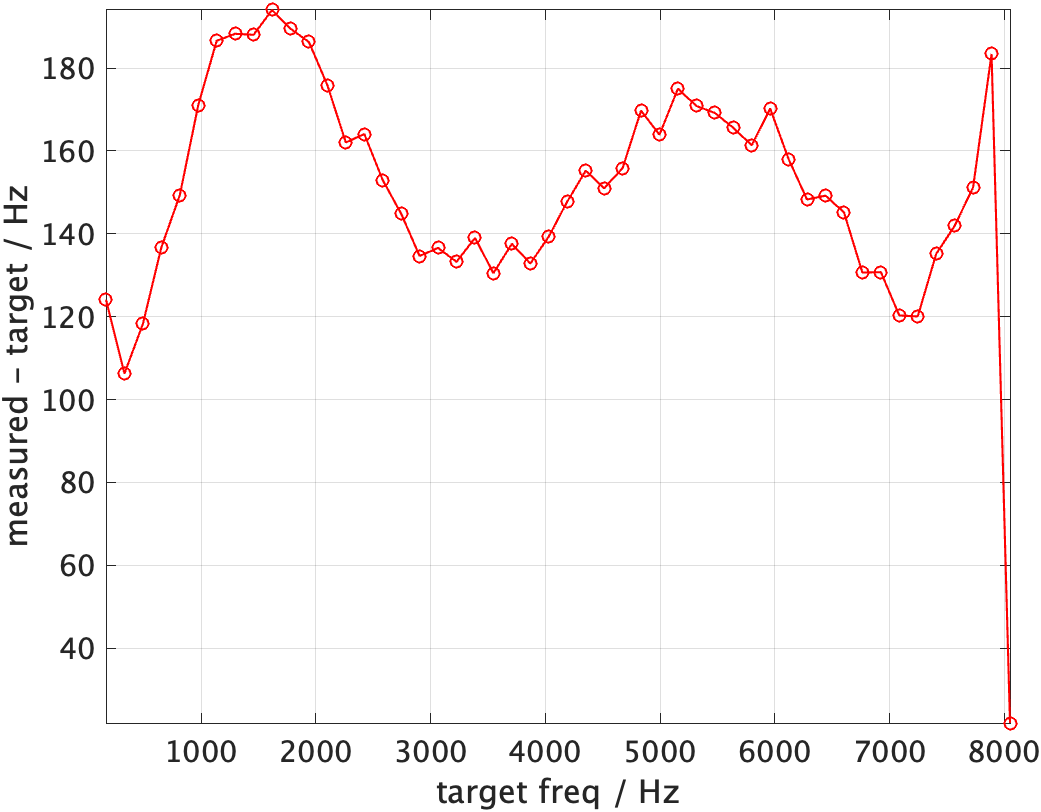

The frequency vs. PWM value curve looked normal other than a glitch on the end ... 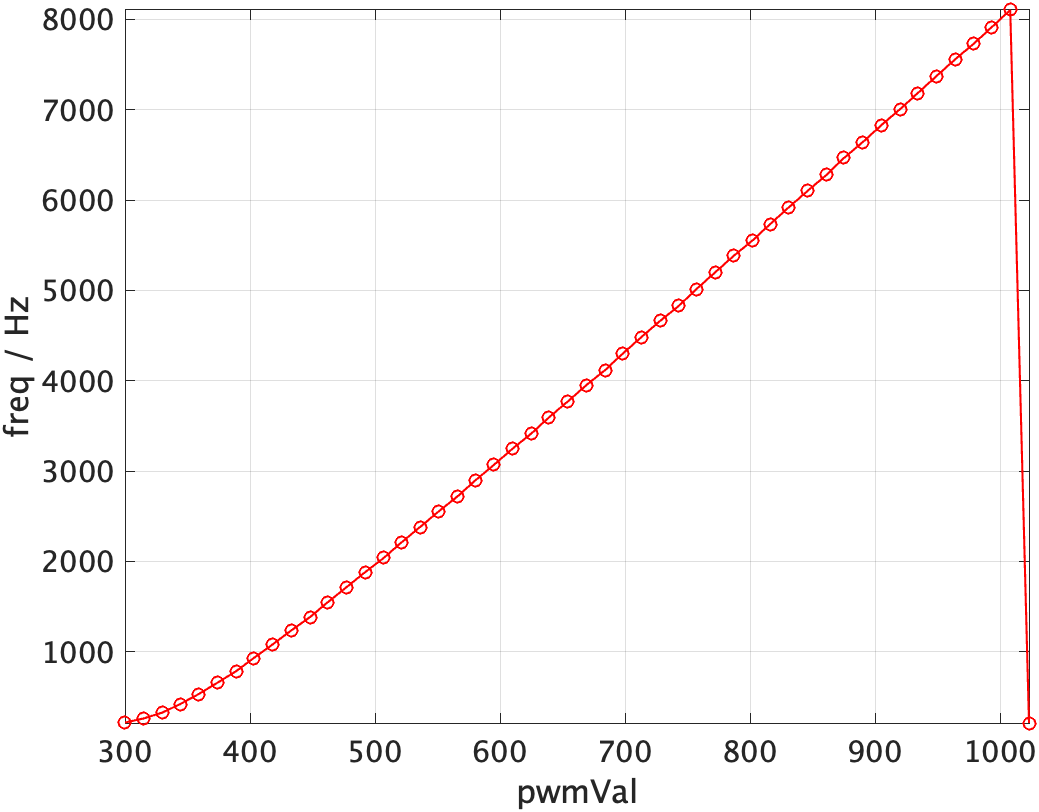

Querying the serial port revealed the cause:

Apparently a 'b' command returned a buffer but it wasn't read nor flushed. Since the port is FIFO, first in first out (as opposed to FAFO ... look that acronym up), this results in a frame shift of the data -- a really nasty error. Solution is `>> flush(pico)`. And part of the solution is to insert this line so it executes automatically before each data acquisition loop -- so instead of a human having to remember it, the software does. 